simOut = out.MotorPowerOut(1)

simOut = struct with fields:
         time: [75362×1 double]
      signals: [1×4 struct]
    blockName: 'CPR_Controller/Motor Power'


out_ref = out.ScopeData

out_ref = Simulink.SimulationData.Dataset 'ScopeData' with 2 elements

                         Name                BlockPath                             
                         __________________  _____________________________________ 
    1  [1x1 Signal]      Rack Position       CPR_Controller/Reference and Position
    2  [1x1 Signal]      Reference Position  CPR_Controller/Reference and Position

  - Use braces { } to access, modify, or add elements using index.


P = simOut.signals(2).values   ;     % your instantaneous power vector
t = simOut.time;

p = out_ref

p = Simulink.SimulationData.Dataset 'ScopeData' with 2 elements

                         Name                BlockPath                             
                         __________________  _____________________________________ 
    1  [1x1 Signal]      Rack Position       CPR_Controller/Reference and Position
    2  [1x1 Signal]      Reference Position  CPR_Controller/Reference and Position

  - Use braces { } to access, modify, or add elements using index.


rack_pos = out_ref{1}.Values.Data

rack_pos =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ref_pos = out_ref{2}.Values.Data

ref_pos =          0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


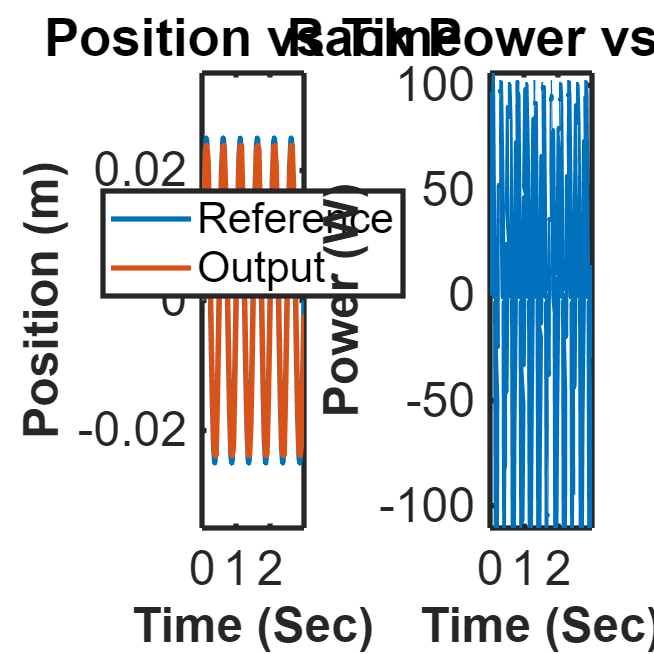


figure
subplot(1, 2, 1)
plot(t,ref_pos)
hold on
plot(t,rack_pos)
title("Position vs Time")
xlabel("Time (Sec)")
ylabel("Position (m)")
legend("Reference", "Output")
ylim([-0.035, 0.035])

subplot(1, 2, 2)
plot(t,P)
title("Rack Power vs Time")
xlabel("Time (Sec)")
ylabel("Power (W)")
improvePlot